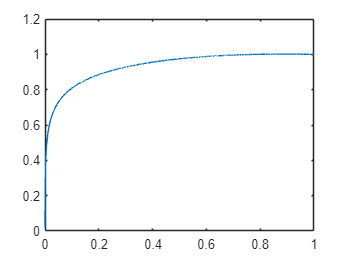



%plot = @(x) (log10(x)+2.3)/2.905 - x^2/500
%fplot(plot, [0 6])
n = 10000;
x0 = 0;
xe = 1;
x= linspace(x0,xe, n);
y = (log10(6*x)+3.3)/3.805 - (6*x).^2/500;
%double()
plot(x,y)

dx = (xe-x0)/n;
dy= (log10(6*(x+dx)+3.3)/3.805 - (6*(x+dx).^2/500)) - ((log10(6*x)+3.3)/3.805 - (6*x).^2/500);
cosA = dx./dy

cosA =          0    0.0009    0.0027   -0.0104   -0.0024   -0.0015   -0.0011   -0.0009   -0.0008   -0.0007   -0.0007   -0.0006   -0.0006   -0.0006   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0005   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0004   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003


Kat = acosd(cosA)-90;
suma=0;
for v=1:n
    suma = suma+abs(Kat(v));
end
suma

suma = 80.5983